[mics, fs] = audioread("double_mics.wav");
ref = mics(:, 2);
target = mics(:, 1);

cutoff = 400;

target = highpass(target, cutoff, fs);
ref = highpass(ref, cutoff, fs);


step_sizes = [.001, .01, .1, .5, .9];
ir_lens = [32, 64, 128, 256, 512, 1024];


N = length(step_sizes);

max_iters = 100;

mses = zeros(N, max_iters);
preds = zeros(N, length(target));
factors = zeros(N, 1);

panel_ir = clipped_irs(128, 2);
panel_ir = highpass(panel_ir, cutoff, fs);

best_filt = FxLMS(ref, target, panel_ir, 256, .05);

min_mse = 100;
min_i = 0;
min_j = 0;

ir_len = 128;

for i = 1:N
    step_size = step_sizes(i);
    source_to_ref_cm = 2;

    panel_ir = clipped_irs(ir_len, source_to_ref_cm);

    filter_order = ir_len * 2;

    
    fxlms = FxLMS(ref, target, panel_ir, filter_order, step_size);
    fxlms.gpu = false;
    [pred_i, mses_i] = fxlms.learn(max_iters);

    mses(i, :) = mses_i;
    preds(i, :) = pred_i;
        
    disp(mses_i)

    if mses_i(end) < min_mse
        min_mse = mses_i(end);
        min_i = i;
        
        best_filt = fxlms;
    end
 

    [ref, target, panel_ir] = denormalize_data(ref, factor, target, panel_ir);
    factors(i) = factor;

    disp('');

end

   1.0e-06 *

    0.1452    0.1086    0.1027    0.0995    0.0975    0.0961    0.0951    0.0943    0.0937    0.0932    0.0928    0.0925    0.0922    0.0920    0.0918    0.0916    0.0915    0.0914    0.0913    0.0912    0.0911    0.0910    0.0909    0.0909    0.0908    0.0908    0.0907    0.0907    0.0906    0.0906    0.0905    0.0905    0.0905    0.0905    0.0904    0.0904    0.0904    0.0904    0.0903    0.0903    0.0903    0.0903    0.0903    0.0902    0.0902    0.0902    0.0902    0.0902    0.0902    0.0902    0.0902    0.0901    0.0901    0.0901    0.0901    0.0901    0.0901    0.0901    0.0901    0.0901    0.0901    0.0901    0.0900    0.0900    0.0900    0.0900    0.0900    0.0900    0.0900    0.0900    0.0900    0.0900    0.0900    0.0900    0.0900    0.0900    0.0900    0.0900    0.0900    0.0900    0.0900    0.0900    0.0899    0.0899    0.0899    0.0899    0.0899    0.0899    0.0899    0.0899    0.0899    0.0899    0.0899    0.0899    0.0899    0.0899    0.0899    0.0899    0.

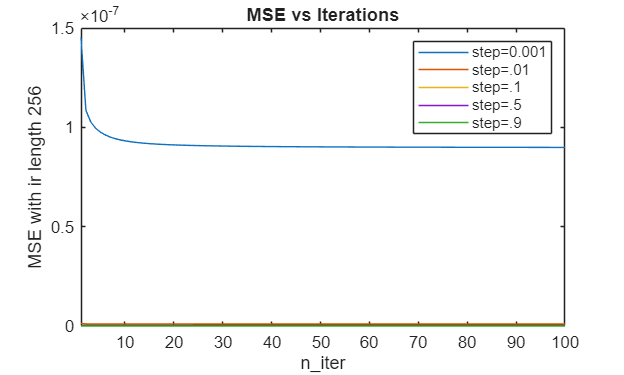

figure
for i = 1:length(step_sizes)
    plot(mses(i, :))
    hold on
end
xlim([1, max_iters])

legend("step=0.001", "step=.01", "step=.1", "step=.5", "step=.9")
xlabel("n\_iter")
ylabel(sprintf("MSE with ir length %d", ir_len))
title("MSE vs Iterations")

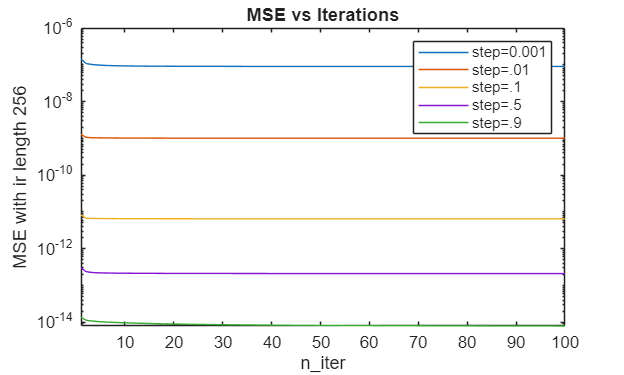

figure
for i = 1:length(step_sizes)
    plot(mses(i, :))
    hold on
end
xlim([1, max_iters])
set(gca, 'YScale', 'log')


legend("step=0.001", "step=.01", "step=.1", "step=.5", "step=.9")
xlabel("n\_iter")
ylabel(sprintf("MSE with ir length %d", ir_len))
title("MSE vs Iterations")

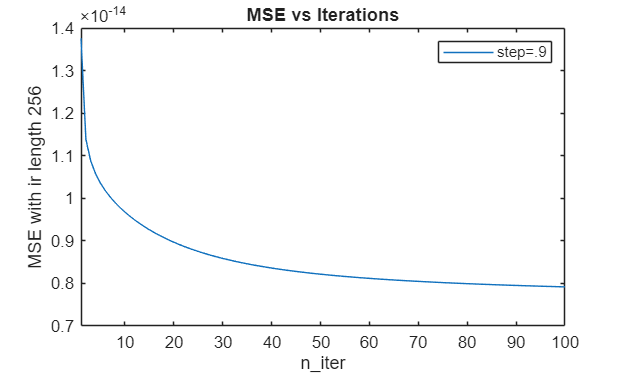

figure
plot(mses(end, :))
xlim([1, max_iters])


legend("step=.9")
xlabel("n\_iter")
ylabel(sprintf("MSE with ir length %d", ir_len))
title("MSE vs Iterations")

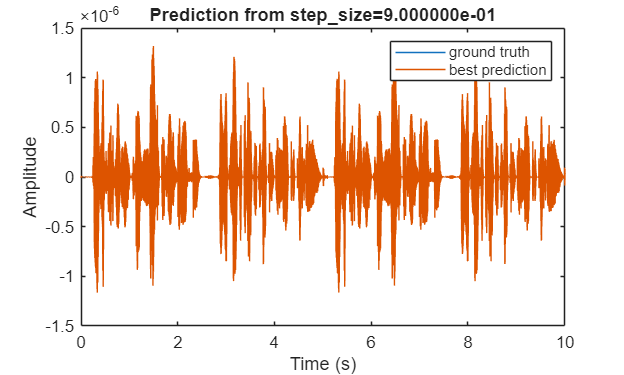

t = (0:length(target) - 1) / fs;
figure
plot(t, target)
hold on
plot(t, squeeze(preds(min_i, :)));
legend("ground truth", "best prediction")
 

title(sprintf('Prediction from step_size=%d', step_sizes(min_i)), 'Interpreter', 'None')
xlabel("Time (s)")
ylabel("Amplitude")
xlim([t(1), t(end)]);

hold off

   1.0e-06 *

    0.2089    0.1994    0.1992    0.1991    0.1990    0.1989    0.1988    0.1988    0.1987    0.1986    0.1986    0.1985    0.1985    0.1984    0.1984    0.1984    0.1983    0.1983    0.1983    0.1982    0.1982    0.1982    0.1982    0.1982    0.1981    0.1981    0.1981    0.1981    0.1981    0.1980    0.1980    0.1980    0.1980    0.1980    0.1980    0.1980    0.1979    0.1979    0.1979    0.1979    0.1979    0.1979    0.1979    0.1979    0.1979    0.1979    0.1978    0.1978    0.1978    0.1978    0.1978    0.1978    0.1978    0.1978    0.1978    0.1978    0.1978    0.1978    0.1977    0.1977    0.1977    0.1977    0.1977    0.1977    0.1977    0.1977    0.1977    0.1977    0.1977    0.1977    0.1977    0.1977    0.1977    0.1976    0.1976    0.1976    0.1976    0.1976    0.1976    0.1976    0.1976    0.1976    0.1976    0.1976    0.1976    0.1976    0.1976    0.1976    0.1976    0.1976    0.1976    0.1976    0.1976    0.1975    0.1975    0.1975    0.1975    0.1975    0.

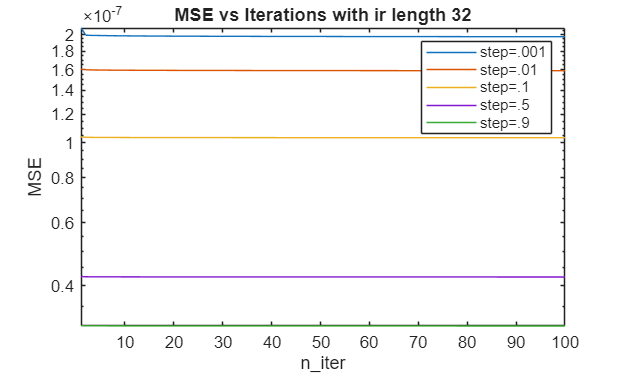

   1.0e-07 *

    0.9660    0.8720    0.8720    0.8773    0.8827    0.8873    0.8911    0.8943    0.8970    0.8992    0.9010    0.9026    0.9040    0.9051    0.9062    0.9071    0.9078    0.9085    0.9092    0.9097    0.9102    0.9107    0.9111    0.9115    0.9119    0.9122    0.9125    0.9128    0.9131    0.9133    0.9136    0.9138    0.9140    0.9142    0.9144    0.9146    0.9147    0.9149    0.9151    0.9152    0.9154    0.9155    0.9156    0.9158    0.9159    0.9160    0.9161    0.9162    0.9163    0.9164    0.9165    0.9166    0.9167    0.9168    0.9169    0.9170    0.9171    0.9172    0.9172    0.9173    0.9174    0.9175    0.9175    0.9176    0.9177    0.9177    0.9178    0.9179    0.9179    0.9180    0.9180    0.9181    0.9181    0.9182    0.9182    0.9183    0.9183    0.9184    0.9184    0.9185    0.9185    0.9186    0.9186    0.9187    0.9187    0.9187    0.9188    0.9188    0.9189    0.9189    0.9189    0.9190    0.9190    0.9190    0.9191    0.9191    0.9191    0.9192    0.

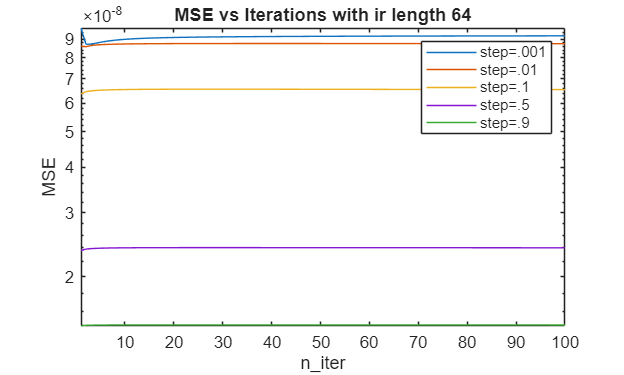

   1.0e-07 *

    0.7255    0.4040    0.3140    0.2681    0.2402    0.2216    0.2086    0.1992    0.1922    0.1869    0.1828    0.1796    0.1771    0.1752    0.1736    0.1723    0.1713    0.1704    0.1697    0.1692    0.1687    0.1683    0.1679    0.1676    0.1673    0.1671    0.1669    0.1667    0.1665    0.1664    0.1662    0.1661    0.1660    0.1658    0.1657    0.1656    0.1655    0.1654    0.1653    0.1652    0.1651    0.1650    0.1649    0.1649    0.1648    0.1647    0.1646    0.1645    0.1645    0.1644    0.1643    0.1643    0.1642    0.1641    0.1641    0.1640    0.1639    0.1639    0.1638    0.1637    0.1637    0.1636    0.1636    0.1635    0.1634    0.1634    0.1633    0.1633    0.1632    0.1632    0.1631    0.1631    0.1630    0.1630    0.1629    0.1629    0.1628    0.1628    0.1627    0.1627    0.1626    0.1626    0.1625    0.1625    0.1624    0.1624    0.1624    0.1623    0.1623    0.1622    0.1622    0.1621    0.1621    0.1621    0.1620    0.1620    0.1619    0.1619    0.

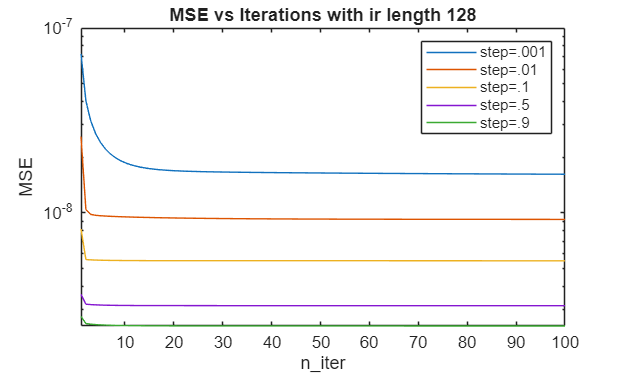

   1.0e-06 *

    0.1181    0.0872    0.0775    0.0715    0.0675    0.0647    0.0626    0.0610    0.0598    0.0588    0.0581    0.0574    0.0569    0.0565    0.0561    0.0557    0.0555    0.0552    0.0550    0.0548    0.0546    0.0544    0.0543    0.0542    0.0540    0.0539    0.0538    0.0537    0.0536    0.0535    0.0535    0.0534    0.0533    0.0533    0.0532    0.0531    0.0531    0.0530    0.0530    0.0529    0.0529    0.0529    0.0528    0.0528    0.0528    0.0527    0.0527    0.0527    0.0526    0.0526    0.0526    0.0526    0.0525    0.0525    0.0525    0.0525    0.0525    0.0524    0.0524    0.0524    0.0524    0.0524    0.0524    0.0524    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0522    0.0522    0.0522    0.0522    0.0522    0.0522    0.0522    0.0522    0.0522    0.0522    0.0522    0.0522    0.0522    0.0522    0.0522    0.0522    0.0521    0.0521    0.0521    0.0521    0.0521    0.0521    0.0521    0.0521    0.

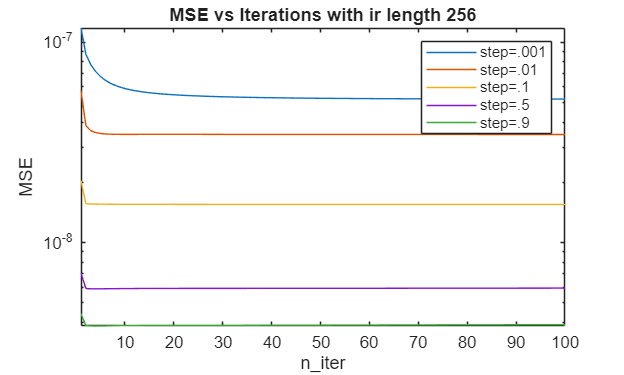

   1.0e-06 *

    0.1078    0.0699    0.0608    0.0550    0.0508    0.0474    0.0445    0.0422    0.0401    0.0384    0.0369    0.0355    0.0343    0.0333    0.0323    0.0315    0.0307    0.0300    0.0294    0.0288    0.0283    0.0278    0.0274    0.0270    0.0266    0.0263    0.0260    0.0257    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0238    0.0236    0.0235    0.0233    0.0232    0.0231    0.0230    0.0228    0.0227    0.0226    0.0226    0.0225    0.0224    0.0223    0.0222    0.0221    0.0221    0.0220    0.0219    0.0219    0.0218    0.0218    0.0217    0.0217    0.0216    0.0216    0.0215    0.0215    0.0214    0.0214    0.0214    0.0213    0.0213    0.0213    0.0212    0.0212    0.0212    0.0211    0.0211    0.0211    0.0210    0.0210    0.0210    0.0210    0.0209    0.0209    0.0209    0.0209    0.0209    0.0208    0.0208    0.0208    0.0208    0.0208    0.0207    0.0207    0.0207    0.0207    0.0207    0.0207    0.0207    0.0206    0.

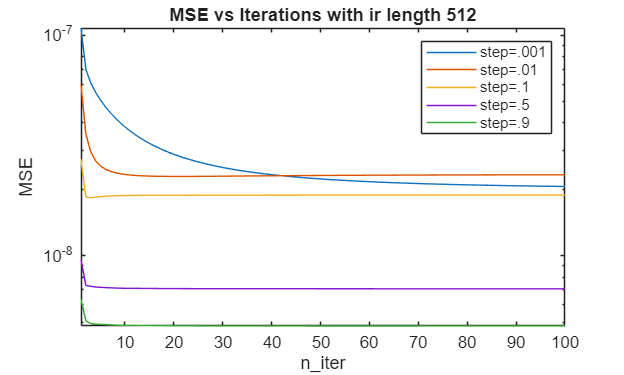

   1.0e-06 *

    0.1296    0.0880    0.0771    0.0705    0.0659    0.0624    0.0597    0.0575    0.0556    0.0540    0.0525    0.0511    0.0499    0.0488    0.0477    0.0467    0.0458    0.0449    0.0441    0.0433    0.0425    0.0418    0.0411    0.0405    0.0399    0.0393    0.0387    0.0382    0.0376    0.0371    0.0367    0.0362    0.0358    0.0353    0.0349    0.0345    0.0341    0.0338    0.0334    0.0331    0.0327    0.0324    0.0321    0.0318    0.0315    0.0312    0.0309    0.0307    0.0304    0.0302    0.0299    0.0297    0.0294    0.0292    0.0290    0.0288    0.0286    0.0284    0.0282    0.0280    0.0278    0.0277    0.0275    0.0273    0.0271    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0258    0.0257    0.0256    0.0255    0.0253    0.0252    0.0251    0.0250    0.0249    0.0248    0.0247    0.0246    0.0245    0.0244    0.0243    0.0242    0.0241    0.0240    0.0239    0.0238    0.0237    0.0236    0.0236    0.0235    0.0234    0.

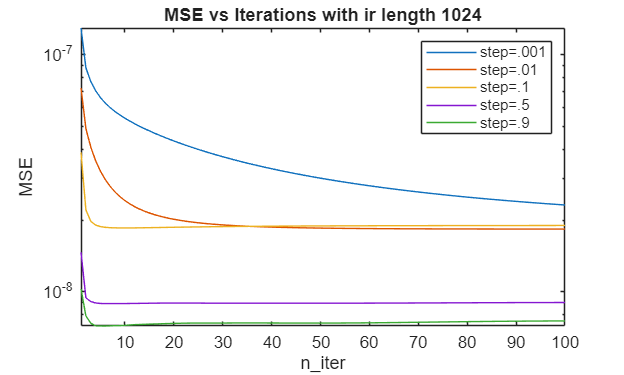

step_sizes = [.001, .01, .1, .5, .9];
ir_lens = [32, 64, 128, 256, 512, 1024];

N = length(step_sizes);

max_iters = 100;

mses = zeros(N, max_iters);
preds = zeros(N, length(target));
factors = zeros(N, 1);

panel_ir = clipped_irs(128, 2);

best_filt = FxLMS(ref, target, panel_ir, 256, .05);

min_mse = 100;
min_i = 0;
min_j = 0;

for j = 1:length(ir_lens)
    ir_len = ir_lens(j);
    for i = 1:N
        step_size = step_sizes(i);
        source_to_ref_cm = 2;
    
        panel_ir = clipped_irs(ir_len, source_to_ref_cm);
        panel_ir = highpass(panel_ir, cutoff, fs);

    
        filter_order = ir_len * 2;
    
        fxlms = FxLMS(ref, target, panel_ir, filter_order, step_size);
        fxlms.gpu = false;
        [pred_i, mses_i] = fxlms.learn(max_iters);
    
        mses(i, :) = mses_i;
        preds(i, :) = pred_i;
            
        disp(mses_i)
    

         
        disp('');
    
    end

    figure
        for i = 1:length(step_sizes)
            plot(mses(i, :))
            hold on
        end
        xlim([1, max_iters])
        set(gca, 'YScale', 'log')
        
        
        legend("step=.001", "step=.01", "step=.1", "step=.5", "step=.9")
        xlabel("n\_iter")
        ylabel("MSE")
        title(sprintf("MSE vs Iterations with ir length %d", ir_len))
end

min_mses = [.3095e-7, .1473e-7, .2445e-8, .3894e-8, .4806e-8, .0754e-7];

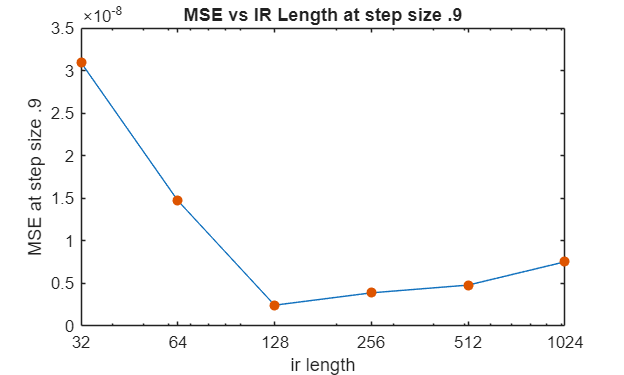

figure
plot(ir_lens, min_mses)
hold on
scatter(ir_lens, min_mses, 'filled')
set(gca, 'XScale', 'log')
xlabel('ir length')
ylabel('MSE at step size .9')
title('MSE vs IR Length at step size .9')
xticks(ir_lens)

step_sizes = [.9, 1, 1.5, 2];

N = length(step_sizes);

max_iters = 100;

mses = zeros(N, max_iters);
preds = zeros(N, length(target));
factors = zeros(N, 1);

panel_ir = clipped_irs(128, 2);
panel_ir = highpass(panel_ir, cutoff, fs);

best_filt = FxLMS(ref, target, panel_ir, 256, .05);

min_mse = 100;
min_i = 0;
min_j = 0;

ir_len = 128;

for i = 1:N
    step_size = step_sizes(i);
    source_to_ref_cm = 2;

    panel_ir = clipped_irs(ir_len, source_to_ref_cm);
    panel_ir = highpass(panel_ir, cutoff, fs);

    filter_order = ir_len * 2;

    
    fxlms = FxLMS(ref, target, panel_ir, filter_order, step_size);
    fxlms.gpu = false;
    [pred_i, mses_i] = fxlms.learn(max_iters);

    mses(i, :) = mses_i;
    preds(i, :) = pred_i;
        
    disp(mses_i)

    if mses_i(end) < min_mse
        min_mse = mses_i(end);
        min_i = i;
        
        best_filt = fxlms;
    end
 
    disp('');

end

   1.0e-08 *

    0.2757    0.2522    0.2502    0.2488    0.2479    0.2473    0.2468    0.2464    0.2461    0.2459    0.2457    0.2455    0.2454    0.2453    0.2452    0.2451    0.2450    0.2450    0.2449    0.2449    0.2449    0.2448    0.2448    0.2448    0.2448    0.2448    0.2447    0.2447    0.2447    0.2447    0.2447    0.2447    0.2447    0.2447    0.2447    0.2447    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2446    0.2445    0.2445    0.2445    0.2445    0.2445    0.2445    0.2445    0.2445    0.2445    0.2445    0.2445    0.2445    0.2445    0.2445    0.2445    0.2445    0.

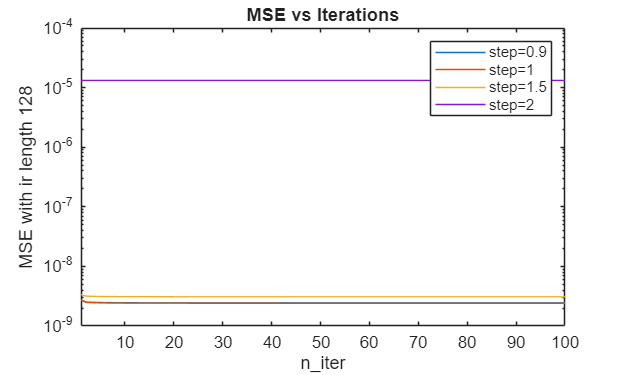

figure
for i = 1:length(step_sizes)
    plot(mses(i, :))
    hold on
end
xlim([1, max_iters])
set(gca, 'YScale', 'log')


legend("step=0.9", "step=1", "step=1.5", "step=2")
xlabel("n\_iter")
ylabel(sprintf("MSE with ir length %d", ir_len))
title("MSE vs Iterations")

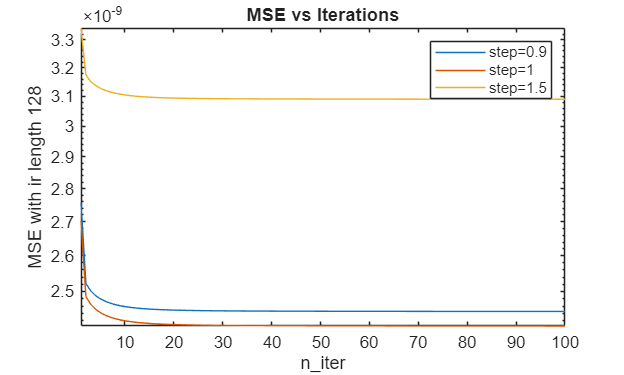


figure
for i = 1:length(step_sizes)-1
    plot(mses(i, :))
    hold on
end
xlim([1, max_iters])
set(gca, 'YScale', 'log')


legend("step=0.9", "step=1", "step=1.5")
xlabel("n\_iter")
ylabel(sprintf("MSE with ir length %d", ir_len))
title("MSE vs Iterations")